# ROOM ACUSTICS:

## Chapter 4: Geometrical Acoustics

### The Virtual Image Method.

Let as consider a sound source, S, placed at (xs, ys, zs), and a reflecting plane, define by its equation:

$\Pi(x,y,z) = Ax+By+Cz+D=0$           (1).

Our problem consists in calculating a point with is symmetrically placed in the direction of the normal  to the reflecting surface. i.e, it is desired to calculate if the position vector of the Virtual Source, $\vec{R}$,  provided the position vector of the source S,  $\vec{P}$, is known.

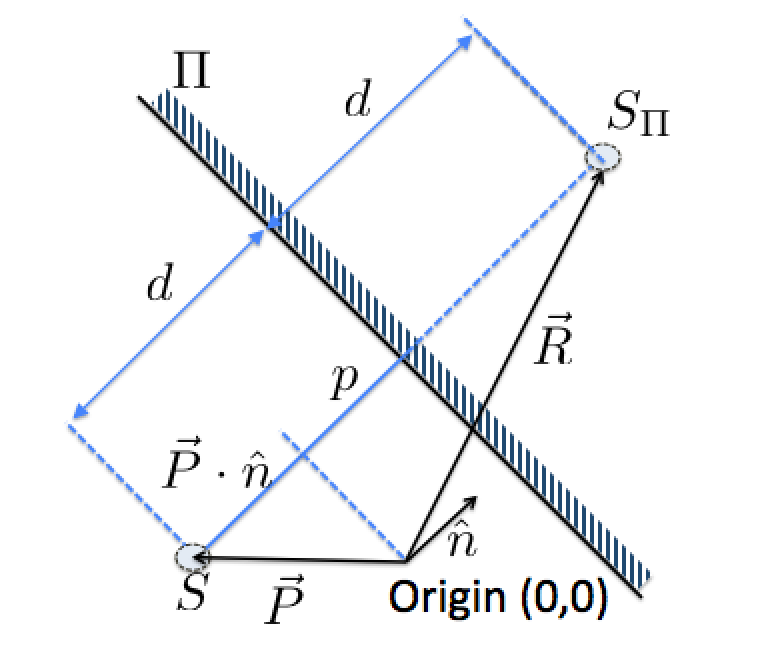

In the figure: 

- $p$ is the distance from the origin (0,0) to the surface:

                            $p=\left | \frac{D}{\sqrt{A^2+B^2+C^2}} \right | $                   (2)

- $d$ is the distance from the Source, S,  to the Surface:

                            $d=p-\vec{P}\cdot \hat{n}$                               (3)

- The position vector R is then obtained as: 

                            $\vec{R}=\vec{P}+2d \hat{n}$                               (4)

### Basic background on Computer simulation using the VI method: 

Data: vertex of the room, the groups of vertex defining the reflecting planes, coeficient of absorption of the materias. 

Definition of a plane: 

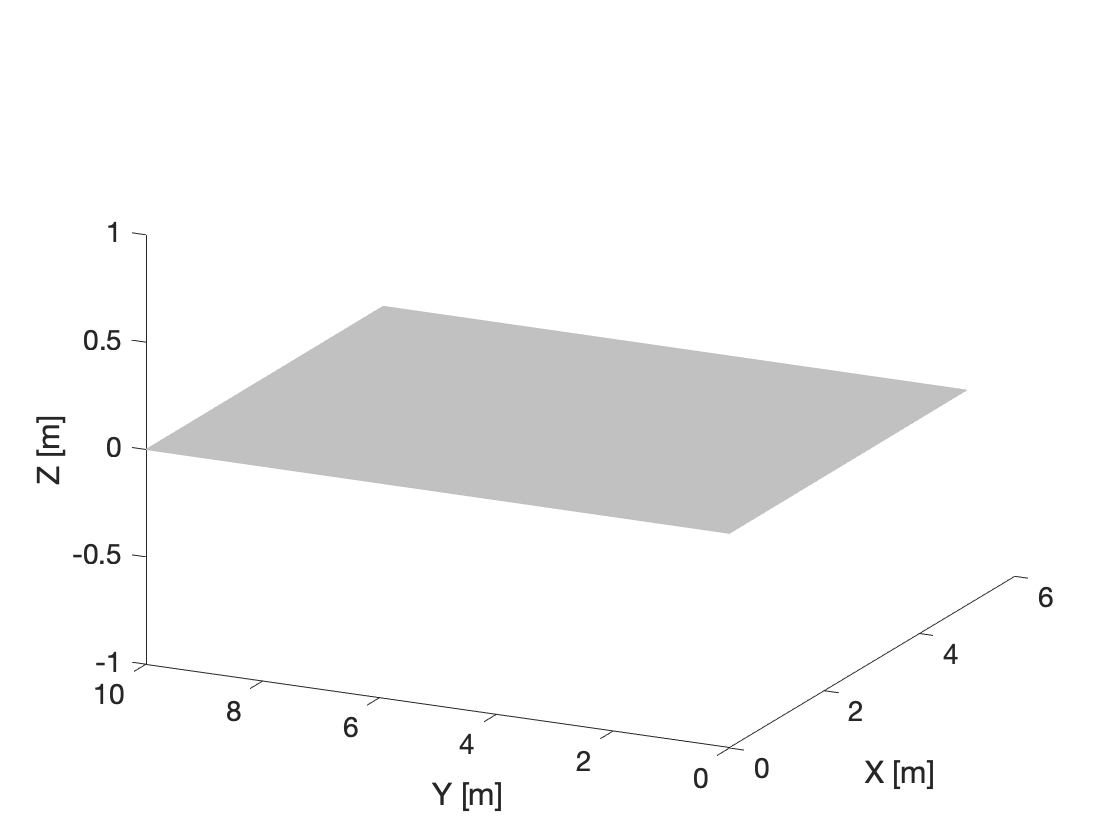

% Points:
P1=[5 0 0]; 
P2=[5 10 0]; 
P3=[0 10 0];
P4=[0 0 0];

Vertex=[P1;P2;P3;P4];

% Faces:
faces=[1 2 3 4];        % Points must be ordered either clockwise or counter clockwise
colores=[0.75 0.75 0.75; 0.75 0.75 0.75;0.75 0.75 0.75;0.75 0.75 0.75;]; % Gray

% Showing the plane:
figure(1);
patch('Vertices', Vertex, 'Faces',faces, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(-64,24)                % Transparency 
grid; 
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');

#### Equation of the plane

First, the equation of the plane defined by the points has to be calculated. Remember that the plane is defined by three points, and the refleting surface could be a poligon containing more than three points belonging to the same plane $\Pi$(x,y,z). Therefore, it should be tested if all the points belongs to the calculated plane (to prevent mistakes or a bad definition of the user).

syms x y z;         % We are making use of the symbolic toolbox of matlab to ease the calculation. 

Plane(x,y,z)=det([x-Vertex(1,1) y-Vertex(1,2) z-Vertex(1,3); Vertex(2,1)-Vertex(1,1) Vertex(2,2)-Vertex(1,2) Vertex(2,3)-Vertex(1,3);
Vertex(3,1)-Vertex(1,1) Vertex(3,2)-Vertex(1,2) Vertex(3,3)-Vertex(1,3)]);
D=Plane(0,0,0); A=Plane(1,0,0)-D; B=Plane(0,1,0)-D; C=Plane(0,0,1)-D;
npuntos = length(Vertex(:,1));
if (npuntos > 3)
        disp('Testing if all points belong to the plane');
         for i=4:npuntos
             if Plane(Vertex(i,1),Vertex(i,2),Vertex(i,3))~= 0
                 error(sprintf('the point (%f,%f,%f) does not belong to the Plane',Vertex(i,1),Vertex(i,2),Vertex(i,3)));
             else
                 disp('OK');
                 EcPlano = double([A B C D])
             end
         end
end

Testing if all points belong to the plane


OK


EcPlano =      0     0    50     0


#### Coordinates of the mirror image:

 First let us define  the source position and acoustic characteristics:

S=[1 1 2];        % Source Position
% Constants
c=343;              % Speed of Sound
roc=415;            % Characteristic Impedance of the air
pref2=4e-10;        % Squared reference for SPL
Wref=1e-12;         % Reference for Lw. 


% Source definition
Lw=90;              % Sound Power of the Source (in decibels)
W=Wref*10^(Lw/10);  % Sound power of the source in (watts)
modulus=norm(EcPlano(1:3));                                          % Modulus of the normal vector of the plane
p = abs(EcPlano(4)/modulus);                                         % Equation (2), distance from the plane to the origin (0,0,0).
n = [EcPlano(1) EcPlano(2) EcPlano(3)]./ norm(EcPlano(1:3));         % Normal vector of the plane 
d = p - n*S';                                                        % Equation (3)
R=S + 2*d*n;  % Coordenadas de la Fuente Virtual                      % Equation (4), position of the virtual image
disp(sprintf(' The potision of the Virtual Image is FV(%0.1f,%0.1f,%0.1f)',R(1),R(2),R(3)));

 The potision of the Virtual Image is FV(1.0,1.0,-2.0)


#### Calculation of the ray path:

Let's define the position of a receiver/listener:

L=[4 3 1];
ray=R-L;                                                % Vector director of the straight line between the Virtual Image and the Listener.
ro = (EcPlano(1:3)*L'+EcPlano(4))/(EcPlano(1:3)*ray');  % Distance from the listener to the surface.
reflexP=L-ro*ray;
disp(sprintf(' The reflexion point between S and L is placed at (%0.1f,%0.1f,%0.1f)',reflexP(1),reflexP(2),reflexP(3)));

 The reflexion point between S and L is placed at (3.0,2.3,0.0)


Let's plot the problem:

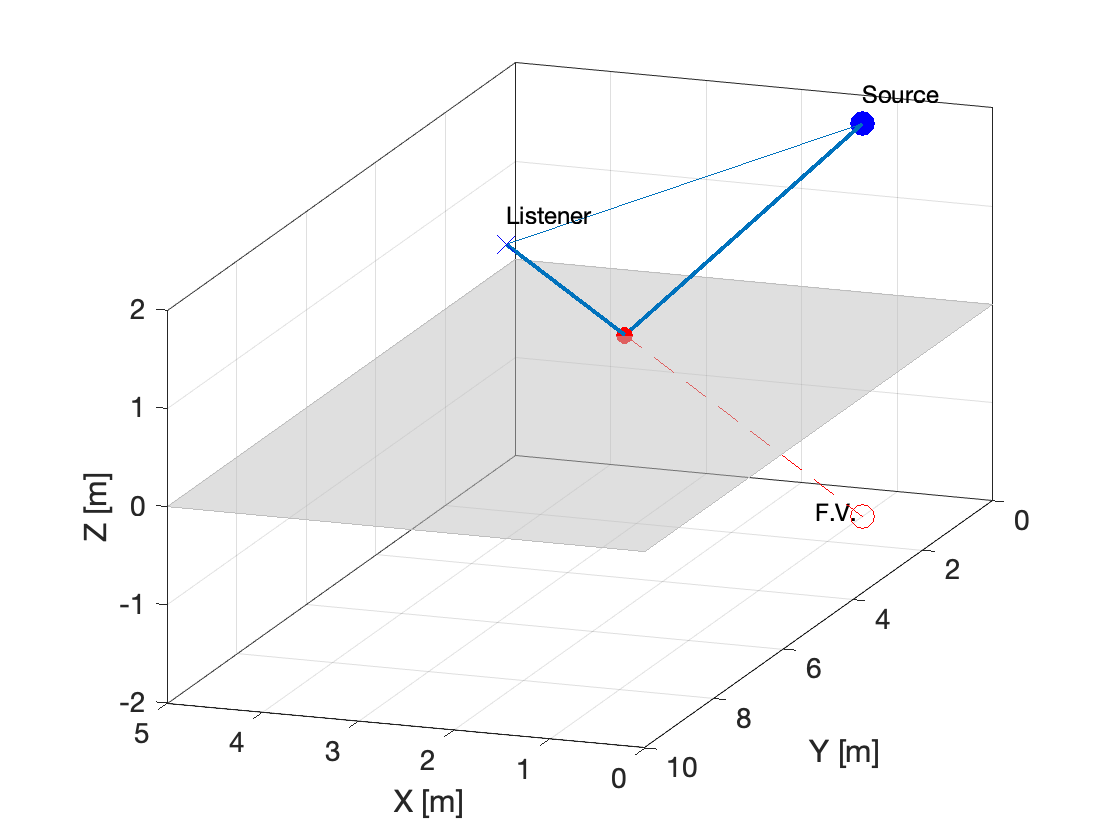

% The plane
figure(2);
patch('Vertices', Vertex, 'Faces',faces, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat'); 
hold on; axis equal; 
alpha(0.5); view(-64,24)                % Transparency 
grid; 
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');

% The points:
plot3(S(1),S(2),S(3),'ob','MarkerFaceColor','b','MarkerSize',12);        % Source
text(S(1),S(2),S(3)+0.3,'Source','FontSize',12);

plot3(L(1),L(2),L(3),'xb','MarkerFaceColor','none','MarkerSize',12);     % Listener
text(L(1),L(2),L(3)+0.3,'Listener','FontSize',12);

plot3(R(1),R(2),R(3),'or','MarkerFaceColor','none','MarkerSize',12);     % Virtual Source
text(R(1)+0.5,R(2),R(3),'F.V.','FontSize',12);

plot3(reflexP(1),reflexP(2),reflexP(3),'or','MarkerFaceColor','r','MarkerSize',8);         % Reflexion Point

% The rays:
    rayd=[S; L];                % Direct
    rayi=[S; reflexP];          % Incident
    rayr=[L; reflexP];          % Reflected
    rayvirt=[R;reflexP];        % Ray between the Virtual Source and the reflexion point
    ld=line(rayd(:,1),rayd(:,2),rayd(:,3));
    li=line(rayi(:,1),rayi(:,2),rayi(:,3));
    lv=line(rayvirt(:,1),rayvirt(:,2),rayvirt(:,3));
    lr=line(rayr(:,1),rayr(:,2),rayr(:,3)); 
    set(li,'LineWidth',2);  set(lr,'LineWidth',2);grid on; 
    set(lv,'LineStyle','--','Color','r');box on; axis equal;
    hold off;   view([200 15]);

### The Impulse Response of a single refexion:

As it is well know, a point source generates a spherical wave (solution of the wave equation in free field conditions). The complex sound pressure of a spherical wave radiated by a monopole source with acoustic power *W *is: 

                                $\tilde{p}(k,r,t)= \rho c W \frac{e^{-jkr}}{4 \pi r} \cdot e^{-j\omega t}$                                    (5)

where *k *is the wavenumber and *r* the distance between the source and a point. 

In our case,  the pressure at the listener is obtained by superposition of the contribution of the direct and the reflected rays:

                $\tilde{p}(k,R_d,R_r,t)= \rho c W \left (\frac{e^{-jkR_d}}{4 \pi R_d} \cdot e^{-j\omega t}+(1-\alpha) \cdot \frac{e^{-jkR_r}}{4 \pi R_r} \cdot e^{-j\omega t} \right )$           (6)

This equation is the frequency response of a reflection on a plane (remember $k=\frac{\omega}{c}$).  Let's see:

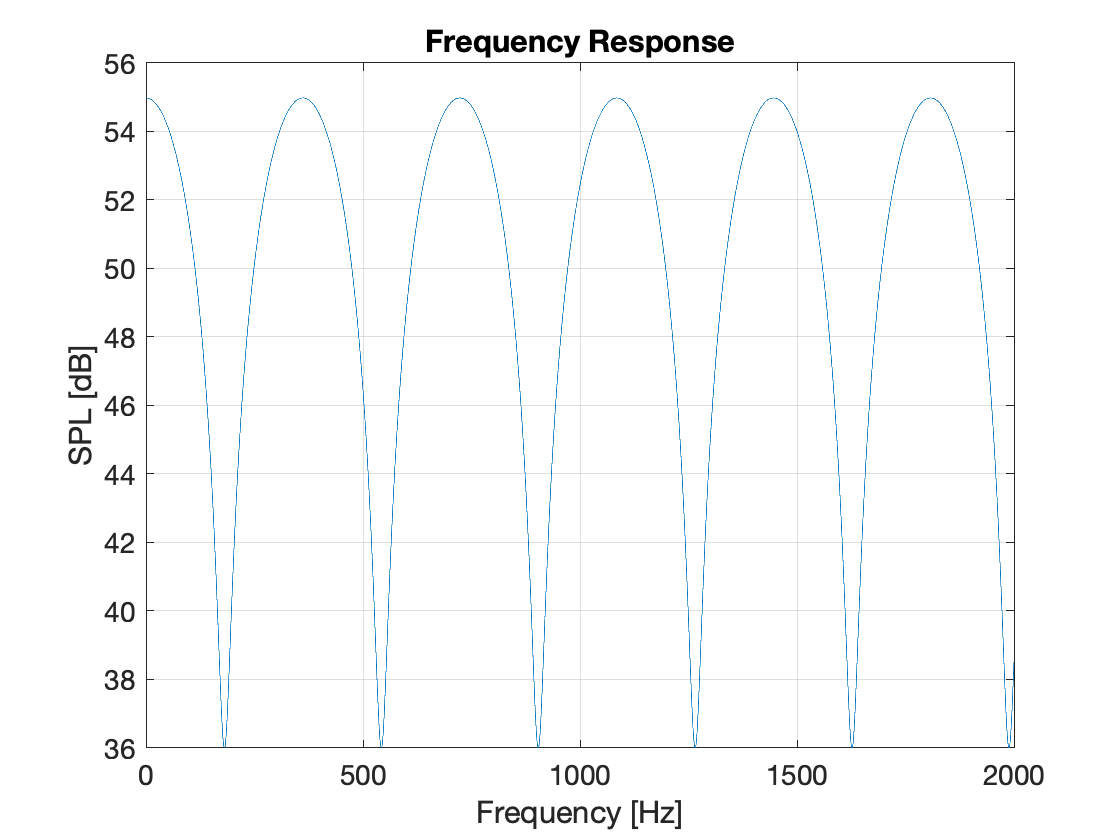

% First, some setups:
fmax= 2000;                 % Maximum frequency to calculate
N=2048*10;                     % Number of points
df= fmax/N;                 % Resolution in frequency
dt=1/N/df;                  % Time resolution    
tmax=dt*N;                  % Maximum time returned when performing ifft.
f=(0:fmax:(N-1)*fmax)/N;    % Frequency axis sampled with N points

w=2*pi*f;
k=w/c;
alfa=0;
    
    Rd=norm(S-L);            % Distance Source-Listener
    Rr=norm(R-L);       % Distance Image Source-Listener
    pl=roc*W*(exp(-1i*k*Rd)/(4*pi*Rd)+(1-alfa)*exp(-1i*k*Rr)/(4*pi*Rr));
    prms=0.5*pl.*conj(pl);
    SPL=10*log10(prms/pref2);
    figure(3);
    plot(f,SPL);grid;
    xlabel('Frequency [Hz]'); ylabel('SPL [dB]');
    title('Frequency Response');xlim([0 2000]);
    set(gca,'FontSize',14);

 Taking the Inverse Fourier Transform of this expression, the impulse response can be obtained. 

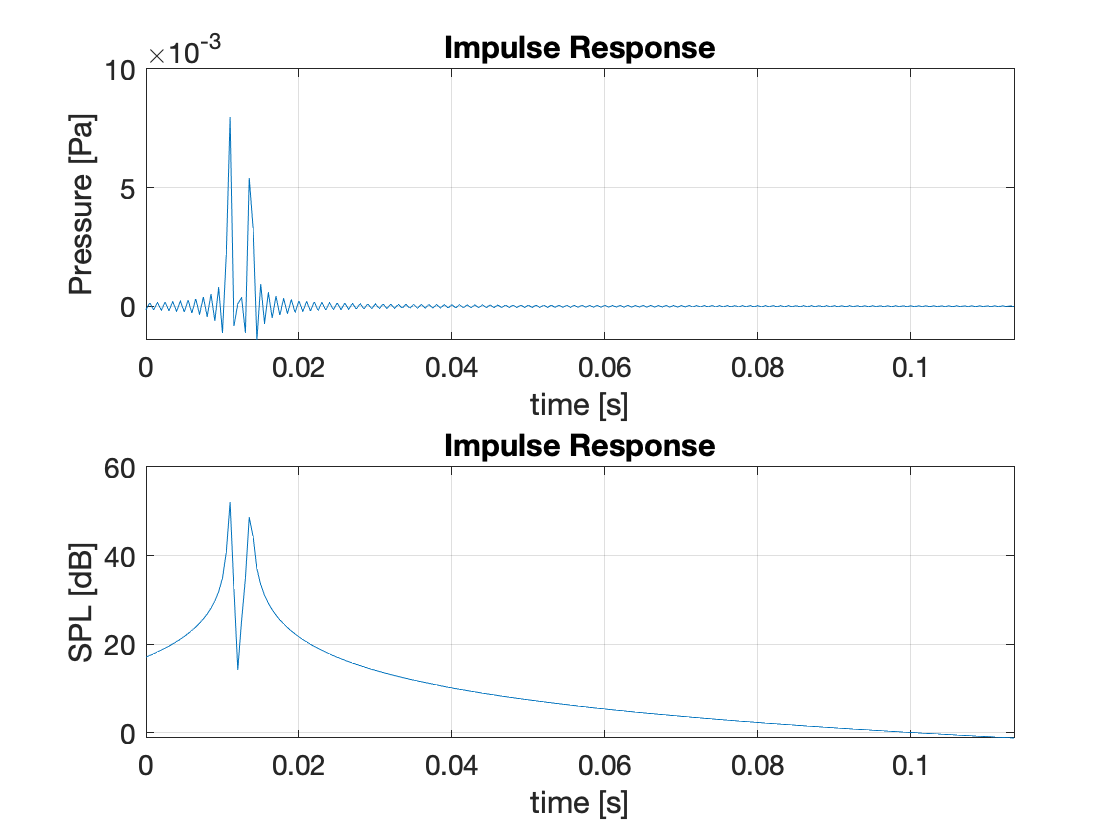

ht=ifft(pl,'symmetric'); % Number of points = fs, means 1 sec of signal. 
t=0:dt:(N-1)*dt;         % Time domain axis
figure(4);
subplot(211);
plot(t,ht); grid; 
[pks,locs]=findpeaks(abs(ht));
xlim([0 t(locs(2))+0.1])
title('Impulse Response');
xlabel('time [s]');
ylabel('Pressure [Pa]'); set(gca,'FontSize',14);
subplot(212);
plot(t,10*log10(ht.^2/4e-10)); grid; 
title('Impulse Response');
xlabel('time [s]');
ylabel('SPL [dB]'); set(gca,'FontSize',14);
xlim([0 t(locs(2))+0.1])

### The visibility problem

The equation of a plane models an infinity surface. A reflecting surface is a finite poligon which is included in the plane. The interserction between the ray from the virtual image to the receiver  can lie outside the reflecting surface. This means that the virtual image is not visible from the receiver and the reflexion is not valid. It should be tested that the intersection calculated is inside the reflecting surface. 

Let's see an example: 

% A big plane:
% Points
P5=[-10 0 0]; 
P6=[10 0 0]; 
P7=[10 0 20];
P8=[-10 0 20];

% A small reflecting surface inside the plane:
P9=[0 0 3]; 
P10=[3 0 3]; 
P11=[3 0 5];
P12=[0 0 5];

Vertex2=[P5; P6; P7; P8; P9;P10;P11;P12];
faces2=[1 2 3 4; 5 6 7 8;];
colors=[colores;1 0 0; 1 0 0; 1 0 0;1 0 0];  % The small reflecting surface will be shown in red.

% Sources
S1=[-2 1.5 3];
S2=[2.5 1.5 4];

% Receiver
L2=[5 1.5 4];

% Plane eq. 
plane1=planec(Vertex2(1:4,:));

Testing if all points belong to the plane
OK



% Virtual Images
R1=fv(plane1,S1);
R2=fv(plane1,S2);

% Intersections:
refl1= intersecta(L2,R1,plane1);
refl2= intersecta(L2,R2,plane1);

% Verification:
in1 = pip(refl1,Vertex2(5:8,:));
if in1==1, 
    str='IN'; else str='OUT';
end; 
   disp(sprintf('The reflexion from S1 is %s the reflecting surface',str));

The reflexion from S1 is IN the reflecting surface



in2 = pip(refl2,Vertex2(5:8,:));
if in2==1, str='IN';  else str='OUT'; 
end;
   disp(sprintf('The reflexion from S2 is %s the reflecting surface',str));

The reflexion from S2 is OUT the reflecting surface


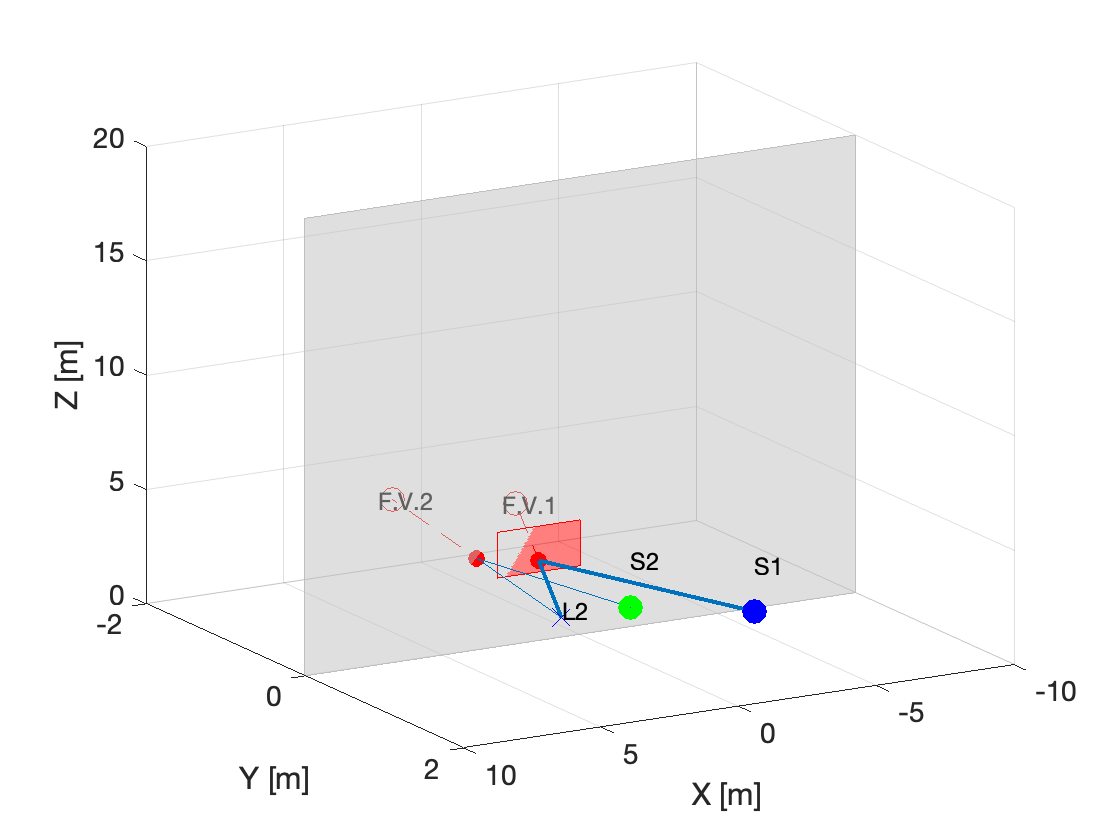


% Showing:
figure;
patch('Vertices', Vertex2, 'Faces',faces2, 'FaceVertexCData', colors, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
% The points:
plot3(S1(1),S1(2),S1(3),'ob','MarkerFaceColor','b','MarkerSize',12);        % Source 1
text(S1(1),S1(2),S1(3)+2,'S1','FontSize',12);
plot3(S2(1),S2(2),S2(3),'og','MarkerFaceColor','g','MarkerSize',12);        % Source 2
text(S2(1),S2(2),S2(3)+2,'S2','FontSize',12);
plot3(L2(1),L2(2),L2(3),'xb','MarkerFaceColor','none','MarkerSize',12);     % Listener
text(L2(1),L2(2),L2(3)+0.3,'L2','FontSize',12);

plot3(R1(1),R1(2),R1(3),'or','MarkerFaceColor','none','MarkerSize',12);     % Virtual Source 1
text(R1(1)+0.5,R1(2),R1(3),'F.V.1','FontSize',12);
plot3(R2(1),R2(2),R2(3),'or','MarkerFaceColor','none','MarkerSize',12);     % Virtual Source 2
text(R2(1)+0.5,R2(2),R2(3),'F.V.2','FontSize',12);


plot3(refl1(1),refl1(2),refl1(3),'or','MarkerFaceColor','r','MarkerSize',8);         % Reflexion Point 1 
plot3(refl2(1),refl2(2),refl2(3),'or','MarkerFaceColor','r','MarkerSize',8);         % Reflexion Point 2

% The rays:
% From S1: 
    rayi1=[S1; refl1];          % Incident, from Source to reflection point. 
    rayr1=[L2; refl1];          % Reflected, from reflection point to L2. 
    rayvirt1=[R1;refl1];        % Ray between the Virtual Source and the reflexion point
% From S2:
    rayi2=[S2; refl2];          % Incident, from Source to reflection point.
    rayr2=[L2; refl2];          % Reflected,  from reflection point to L2. 
    rayvirt2=[R2;refl2];        % Ray between the Virtual Source and the reflexion point
% Once defined the rays, the lines can be drawn:     
    li1=line(rayi1(:,1),rayi1(:,2),rayi1(:,3));
    li2=line(rayi2(:,1),rayi2(:,2),rayi2(:,3));
    lv1=line(rayvirt1(:,1),rayvirt1(:,2),rayvirt1(:,3));
    lv2=line(rayvirt2(:,1),rayvirt2(:,2),rayvirt2(:,3));
    lr1=line(rayr1(:,1),rayr1(:,2),rayr1(:,3)); 
    lr2=line(rayr2(:,1),rayr2(:,2),rayr2(:,3)); 
    set(li1,'LineWidth',2);  set(lr1,'LineWidth',2);grid on;
    set(lv1,'LineStyle','--','Color','r');
    set(lv2,'LineStyle','--','Color','r');
    view([150 20])
    hold off;

### APPLICATION: Coverage of a Reflector: 

- Geometry of the problem:

% Points
 Pr1=[-1 2 4]; 
 Pr2=[1 2 4]; 
 Pr3=[1 5 5];
 Pr4=[-1 5 5];

Vertexr=[Pr1; Pr2; Pr3; Pr4];
facesr= [1 2 3 4];

% Source
Sr=[0 0 0];

% Receivers
x=(-7:0.25:7);
y=(0:0.25:30);
z=0;
[X,Y,Z]=meshgrid(x,y,z);
xyz=[X(1:end)' Y(1:end)' Z(1:end)'];


- VIrtual Image Calculation:

EcPlanor=planec(Vertexr);

Testing if all points belong to the plane
OK


IVr=fv(EcPlanor,Sr),

IVr =          0   -2.0000    6.0000


- Detection of the recever points which can "see" the virtual image, i.e., those receiving a valid reflexion:

[M,N]=size(xyz);
intersecs=zeros(M,3);
IN=zeros(M,1);
for ii=1:M
    aux=intersecta(IVr,xyz(ii,:),EcPlanor);
    IN(ii)=pip(aux,Vertexr);
end
xyzi=[xyz IN];

- Showing the results: 

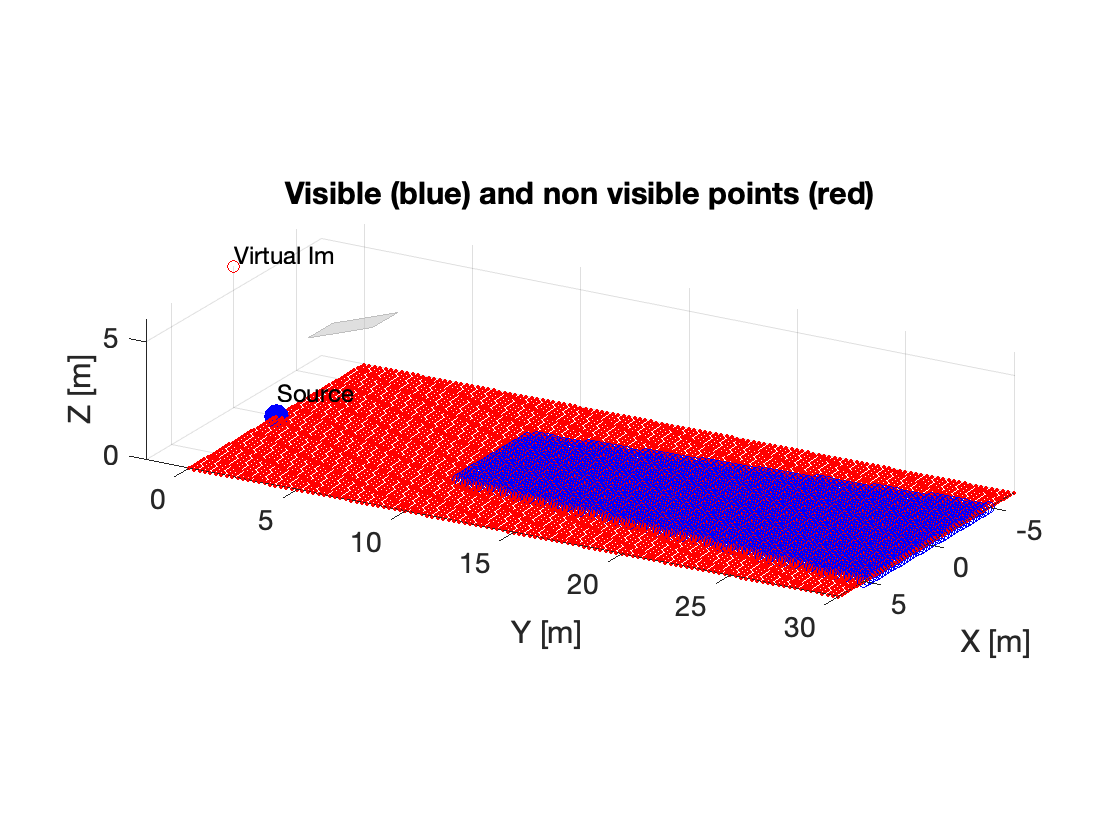

figure;
patch('Vertices', Vertexr, 'Faces',facesr, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');

% Source:
plot3(Sr(1),Sr(2),Sr(3),'ob','MarkerFaceColor','b','MarkerSize',12);        % Source
text(0,0,1,'Source','FontSize',12);

% Receivers:
plot3(X,Y,Z,'.r');

% Virtual Image
plot3(IVr(1),IVr(2),IVr(3),'or');
text(IVr(1),IVr(2),IVr(3)+0.5,'Virtual Im','FontSize',12);
visibles=xyzi(IN==1,:);
plot3(visibles(:,1),visibles(:,2),visibles(:,3),'ob');
view([120 20]);
title('Visible (blue) and non visible points (red)');
axis equal;hold off

- Sound Pressure Level: we consider a non coherent adition of the contributions.

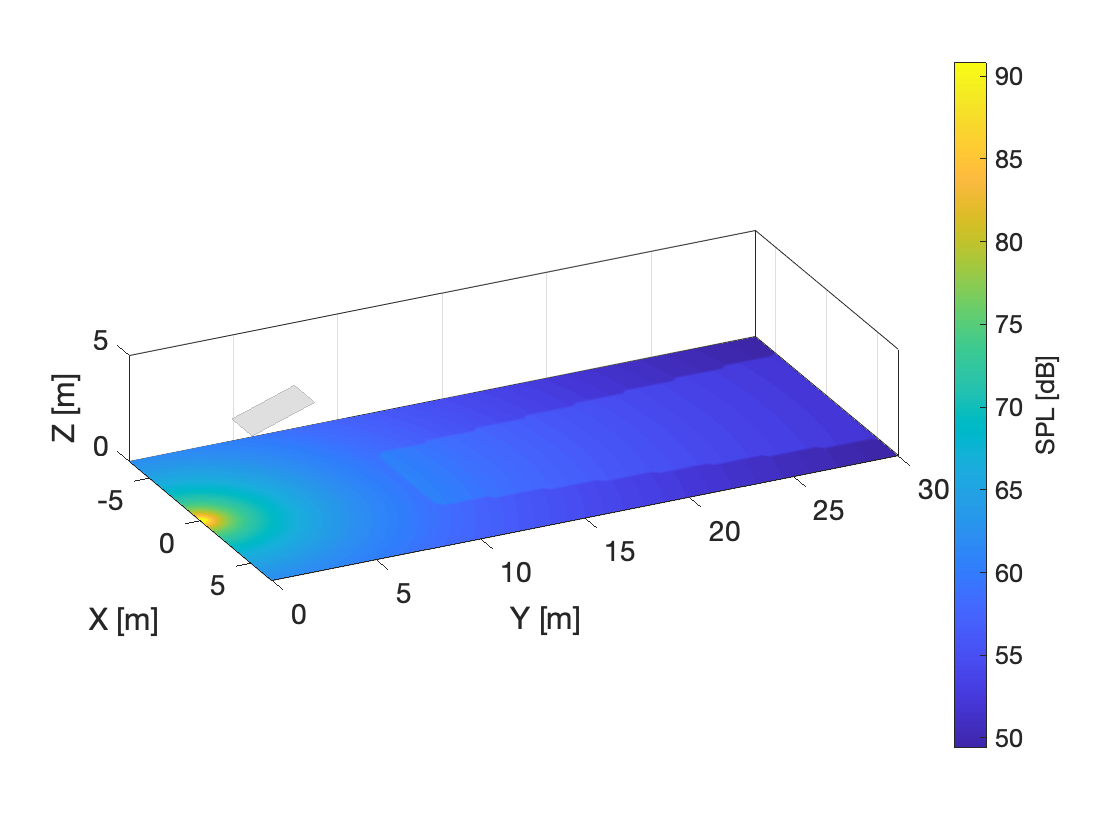

% Distances:

pt=zeros(length(xyz(:,1)),1);
rd2=(Sr(1)-xyz(:,1)).^2+(Sr(2)-xyz(:,2)).^2+(Sr(3)-xyz(:,3)).^2; % Squared distance between source and receivers

rr2=(IVr(1)-visibles(:,1)).^2+(IVr(2)-visibles(:,2)).^2+(IVr(3)-visibles(:,3)).^2; % Squared distance, reflected

pdir2=roc*W./(4*pi*rd2);
preflect2=roc*W./(4*pi*rr2);

pt=pdir2;
pt(IN==1)=pdir2(IN==1)+preflect2;
SPLdir=10*log10(pdir2/pref2);
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);
SPLt=reshape(SPLt,size(X));
SPLdir=reshape(SPLdir,size(X));

%% SHOWING RESULTS:
figure;
patch('Vertices', Vertexr, 'Faces',facesr, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
h=contourf(x,y,SPLt,100,'EdgeColor','none'); box on;colorbar;
caxis([low high-10]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal; 
hold off;

We can notice the increase of the sound pressure level in the coverage region of the reflector.

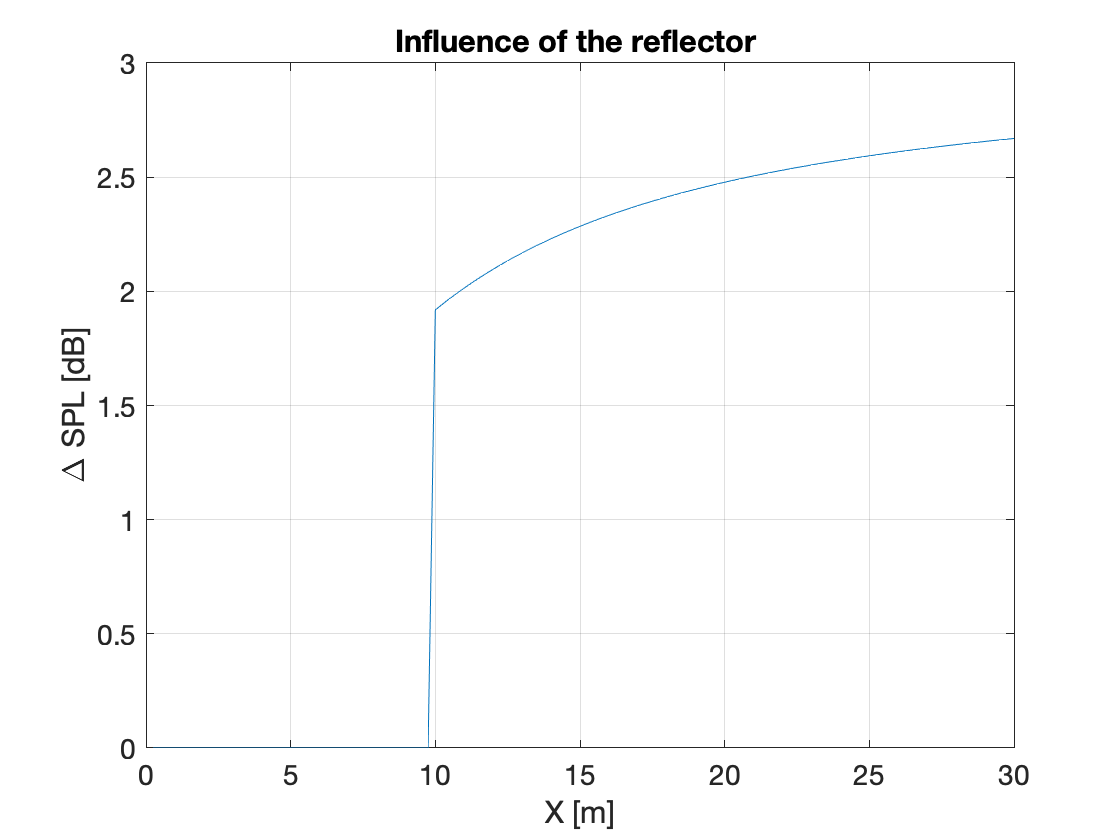

figure(100);
plot(y,SPLt(X==0)-SPLdir(X==0)); grid; 
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('\Delta SPL [dB]'); 
title('Influence of the reflector ')

### Functions:

function y=fv(plane,source);
% Virtual Image
    modulus=norm(plane(1:3));                                          % Modulus of the normal vector of the plane
    p = abs(plane(4)/modulus);                                         % Equation (2), distance from the plane to the origin (0,0,0).
    n = [plane(1) plane(2) plane(3)]./ norm(plane(1:3));         % Normal vector of the plane 
    d = p - n*source';                                                        % Equation (3)
    y=source + 2*d*n;  % Coordenadas de la Fuente Virtual                     % Equation (4), position of the virtual image
end

function EcPlano=planec(Vertex);
% Equation of the plane; 
syms x y z;      % We are making use of the symbolic toolbox of matlab to ease the calculation. 

Plane(x,y,z)=det([x-Vertex(1,1) y-Vertex(1,2) z-Vertex(1,3); Vertex(2,1)-Vertex(1,1) Vertex(2,2)-Vertex(1,2) Vertex(2,3)-Vertex(1,3);
Vertex(3,1)-Vertex(1,1) Vertex(3,2)-Vertex(1,2) Vertex(3,3)-Vertex(1,3)]);
D=Plane(0,0,0); A=Plane(1,0,0)-D; B=Plane(0,1,0)-D; C=Plane(0,0,1)-D;
npuntos = length(Vertex(:,1));
    if (npuntos > 3)
        disp('Testing if all points belong to the plane');
         for i=4:npuntos
             if Plane(Vertex(i,1),Vertex(i,2),Vertex(i,3))~= 0
                 error(sprintf('the point (%f,%f,%f) does not belong to the Plane',Vertex(i,1),Vertex(i,2),Vertex(i,3)));
             else
                 disp('OK');
                 EcPlano = double([A B C D]);
             end
         end
    end
end


function P= intersecta(punto1, punto2, EcPlano);
% Intersection plane-straight line
    directa=punto1-punto2; 
    ro =(EcPlano(1:3)*punto2'+ EcPlano(4))/(EcPlano(1:3)*directa');
    P=punto2-ro*directa;
end

function in = pip(punto,vertices)
% Comprueba la visibilidad de un punto en un pol´?gono (PIP).
% Entrada:
% punto: Coordenadas del punto a comprobar.
% vertices: V´ertices del pol´?gono.
% Salida:
% dentro: Vale 1 si el punto est´a dentro del pol´?gono
    epsilon = 0.000001;
    npuntos = length(vertices(:,1));
    if (npuntos < 3)
        error('Polígono no esta Definido. Menos de tres puntos.');
    end
    % Calculamos los Vectores Ei
    for j=1:npuntos
        E(j,:) = vertices(j,:) - punto;
    end
    angulo =0;% Inicializamos el ´Angulo total
    for j=1:npuntos
        aux = (E(j,:)*E(mod(j,npuntos)+1,:)')/(norm(E(j,:)*norm(E(mod(j,npuntos)+1,:))));
        angulo = angulo + acos(aux);
    end
    % Comprobamos si el ´ Angulo Total es 2? teniendo en cuenta los posibles errores de redondeo,
    %por ello se comprueba si el agulo est´a contenido en el intervalo [2? ? �, 2? + �]
    if ((angulo > 2*pi-epsilon) && (angulo < 2*pi+epsilon))
        in=1;
    else
        in=0;
    end
end
